#     Landmark localization 3d

Simulation of a robot moving in a 2d plane. Measurements are taken by beacons ( which transmit the range back to the robot ) and other sensors.

Date Started : 22 Dec. 2023 , 12 : 30 PM

Author : Giorgio Ridolfi

## Sources in consultation order

1) [https://stackoverflow.com/questions/39818915/matlab-how-to-get-the-specs-of-the-host-machine](https://stackoverflow.com/questions/39818915/matlab-how-to-get-the-specs-of-the-host-machine)

2) [https://undocumentedmatlab.com/](https://undocumentedmatlab.com/)

3) [https://www.youtube.com/playlist?list=PLgnQpQtFTOGQrZ4O5QzbIHgl3b1JHimN_](https://www.youtube.com/playlist?list=PLgnQpQtFTOGQrZ4O5QzbIHgl3b1JHimN_)

## System Info

close all
clc
display("OS : " + computer("arch") + ", " + feature('GetOS') )

    "OS : glnxa64, Linux 5.15.0-91-generic #101-Ubuntu SMP Tue Nov 14 13:30:08 UTC 2023 x86_64"



display("Processor : " + feature('GetCPU') + ", " + feature('numCores') )

    "Processor : 11th Gen Intel(R) Core(TM) i7-11370H @ 3.30GHz, 4"



GPU = gpuDevice

GPU =   CUDADevice with properties:

                      Name: 'NVIDIA GeForce RTX 3050 Laptop GPU'
                     Index: 1
         ComputeCapability: '8.6'
            SupportsDouble: 1
     GraphicsDriverVersion: '525.147.05'
               DriverModel: 'N/A'
            ToolkitVersion: 11.8000
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152 (49.15 KB)
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 4091478016 (4.09 GB)
           AvailableMemory: 3825598464 (3.83 GB)
               CachePolicy: 'balanced'
       MultiprocessorCount: 16
              ClockRateKHz: 1057000
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 1
          CanMapHostMemory: 1
           DeviceSupported: 1
           DeviceAvailable: 1
            Devi

clear all


## Creation of arena

For visual aid

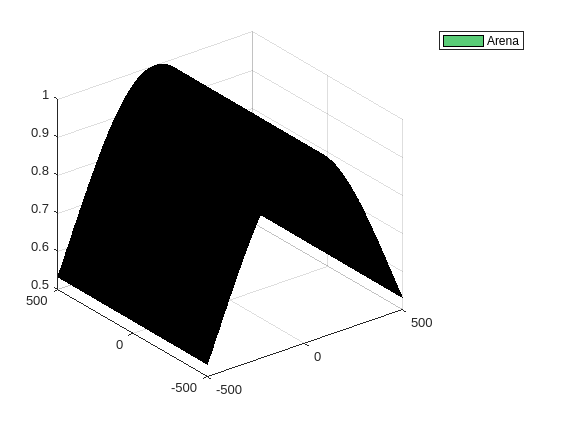

 dim_bound = 500;
 x_arena = [-dim_bound:1:dim_bound];
 y_arena = [-dim_bound:1:dim_bound];
 z_arena = meshgrid(x_arena,y_arena);
 z_arena = exp(-0.00000251*z_arena.^2);
 index = length(x_arena);
 
 figure
 surf(x_arena,y_arena,z_arena)
 hold on
 legend("Arena" )

## Creation of landmarks

These landmarks transmit range and bearing back to the robot

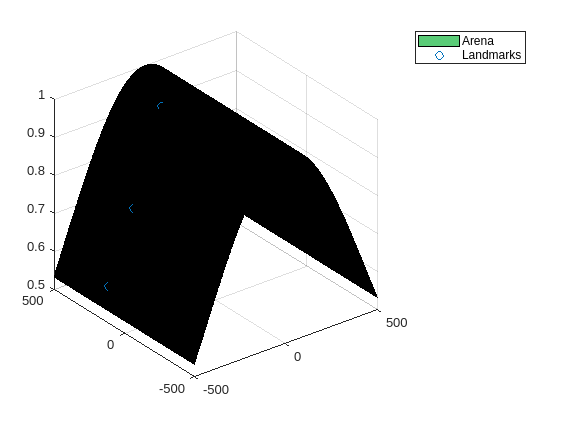

num_landmarks = 5;
coord_landmarks = zeros(3,num_landmarks);
for j = 1 : num_landmarks
    x_lm = randi(index);
    y_lm = randi(index);
    coord_landmarks(:,j) = [ x_arena(x_lm) ; y_arena(y_lm) ; z_arena(x_lm,y_lm)];
end
scatter3(coord_landmarks(2,:) , coord_landmarks(1,:) , coord_landmarks(3,:))
legend("Arena" , "Landmarks" )


clear dim_bound x_arena y_arena z_arena index x_lm y_lm j

## State space and sensor

To have a benchmark for filtering algorithms. Application of Artificial Potential FIeld

x
range = zeros(num_landmarks,N);
bearing = zeros(num_landmarks,N);
stdrange =  1 ;
stdbearing =  1 ;
imu
encoder
x_hat


## Generate sensor data

#### #1 Radar data

Radar with additive gaussian noise


% for i = 1 : N
%  for j = 1 : num_landmarks
%      [ range(j,i) ,  bearing(j,i) ] = hRadar3D( x_arena(:,i) , coord_landmarks(:,j) ) ;
%      range(j,i) = range(j,i) + stdrange*randn();
%      bearing(j,i) = bearing(j,i) + stdbearing*randn();
%  end
% end

#### #2 IMU and Helix encoders

IMUs

## APPENDIX : Functions

function [range_out , bearing_out ] = hRadar3D(x_in , lm_in)
% Usage: pass position of observer ( as a column vector) and coordinates of landmark ( as a column vector ). Order
% should be XYZ on both
    
    dx = x_in(1) - lm_in(1) ;
    dy = x_in(2) - lm_in(2) ;
    dz = x_in(3) - lm_in(3) ;
    range_out = sqrt( dx*dx + dy*dy + dz*dz ) ;
    bearing_out = atan2(dy,dx)  ; 

end
